# 2D Discrete Operators

clear, close all, clc
set_defaults()

## 2D staggered grid

Due to the internal logic of the Matlab functions meshgrid() and reshape() it is best to order the number the unknowns/cells/faces/dof's in the 2D grid in y-direction first and then in x-direction.

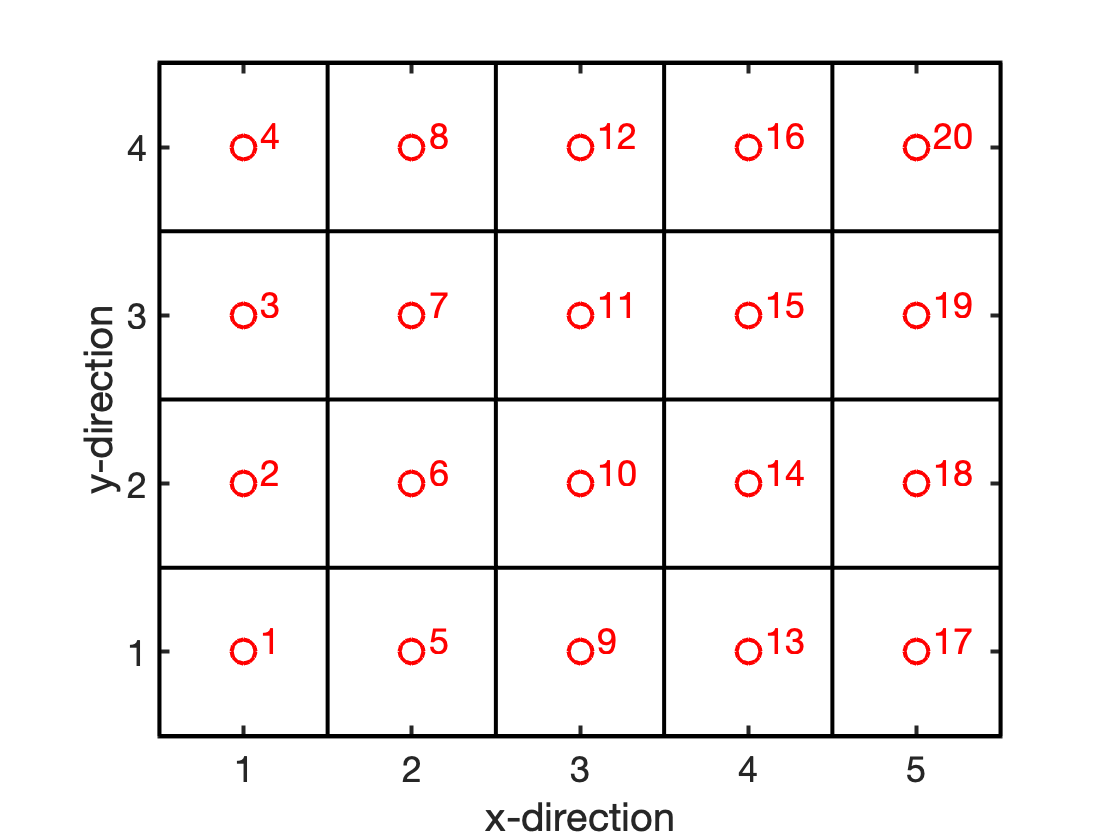

Nx = 5; Ny = 4;
plot_grid(Nx,Ny)

On this grid we need a two discrete operatore:

- Discrete divergence: `D`` = [``Dx``,``Dy``]`

- Discrete gradient:     **G** = [**Gx**;**Gy**]

## Assembly of discrete divergence

The 2D `Dx` and `Dy` are block matrices that are composed of

- 1D divergence and gradient operators

- (scaled) Indentity matrices

- zeros

These matrices can therefore be assembled simply and efficiently using tensor/Kronecker products. 

Last class we have shown that the 2D operators can be defirned in terms of the 1D operators as follows

- `Dx`` = kron(``Dx``,``Iy``);`

- `Dy`` = kron(``Ix``,``Dy``);`

where `Ix` and `Iy` are Nx by Nx and Ny by Ny identity matrices, respectively.

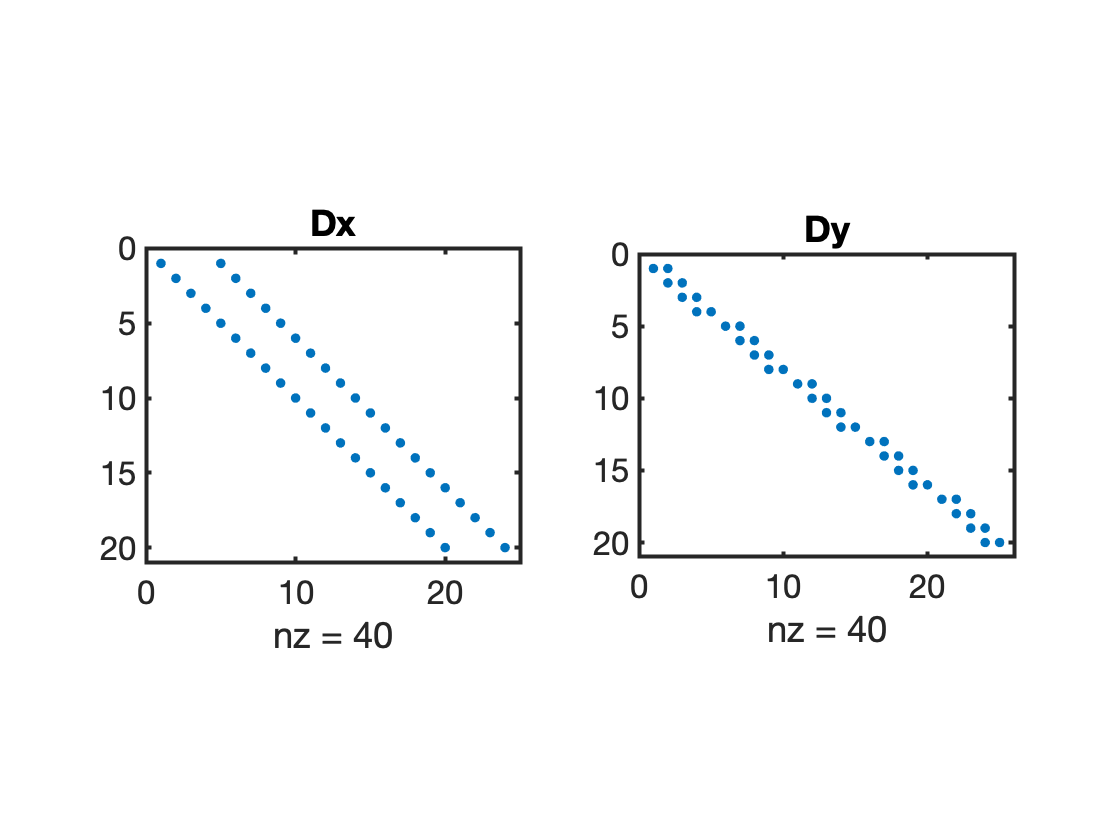

Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = Nx;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = Ny;
Grid = build_grid(Grid);

% Build 2D Dx matrix
Dx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[0 1],Nx,Nx+1);
Iy = speye(Ny);
Dx = kron(Dx,Iy);

% Bulid 2D Dy matrix
Dy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[0 1],Ny,Ny+1);
Ix = speye(Grid.Nx);
Dy = kron(Ix,Dy);

% Full 2D discrete divergence matrix
D = [Dx,Dy];

subplot 121
spy(Dx), title 'Dx'
subplot 122
spy(Dy), title 'Dy'

Note, that 3D operators can be assembled similarly by applying the tensor product to the 2D matrices and `Iz`!

On homework 7, you will assemble the discrete gradient operators using tensor-products, for practice.

## Discrete gradient

While it is straight forward to assemble the gradients directly, it is even more convenient to recognize that the gradient is the adjoint operator of the divergence in the interior of the domain, but has natural boundary conditions (zero gradient) on the exterior. Hence, we obtain `G` as in 1D:

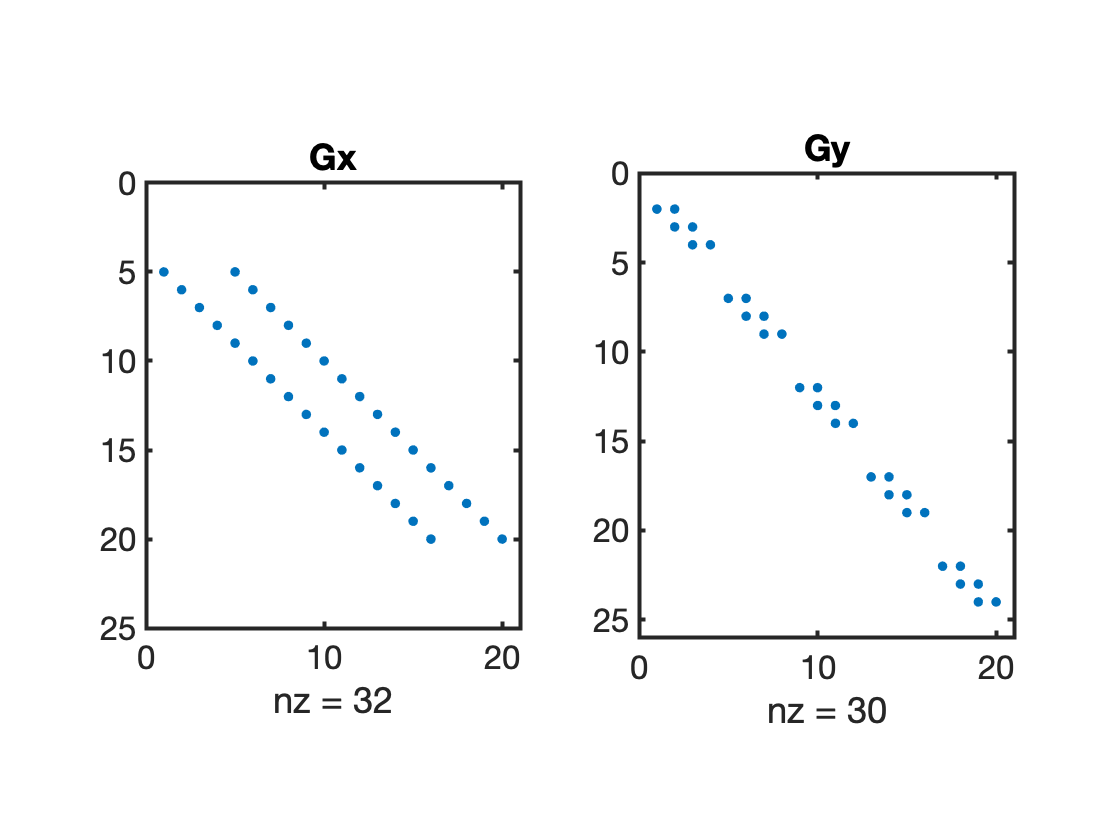

% ADJOINT IN INTERIOR
G = -D';  

% NATUAL BC's ON EXTERIOR
% collect all exterior faces
dof_f_bnd = [Grid.dof_f_xmin; Grid.dof_f_xmax;... 
             Grid.dof_f_ymin; Grid.dof_f_ymax];
% set gradient to zero
G(dof_f_bnd,:) = 0;

% plot
figure
subplot 121
spy(G(1:Grid.Nfx,:)), title 'Gx'
subplot 122
spy(G(Grid.Nfx+1:Grid.Nf,:)), title 'Gy'

## 2D discrete Laplacian

As in 1D the discrete Laplacian in 2D is simply the product of `D` and `G`:

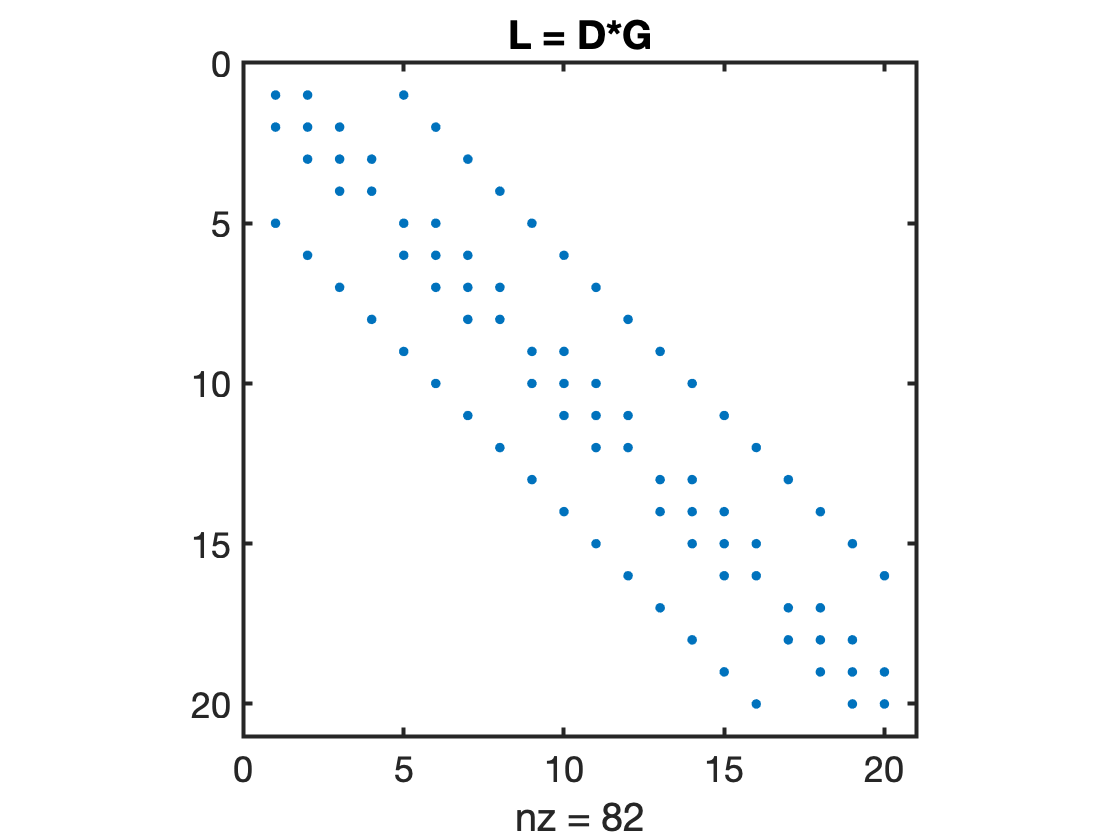

L = D*G;
figure
spy(L), title 'L = D*G'

# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

## plot_grid()

function [] = plot_grid(Nx,Ny)
N = Nx*Ny;

x = 1:Nx;
y = 1:Ny;
dof = 1:N;

[X,Y] = meshgrid(x,y);

DOF = reshape(dof,Ny,Nx);

plot([.5 Nx+.5 Nx+.5 .5 .5],[.5 .5 Ny+.5 Ny+.5 .5],'k'), hold on
for i=1:Nx
    plot([x(i)+.5 x(i)+.5],[.5 Ny+.5],'k-')
    for j=1:Ny
        plot([.5 Nx+.5],[y(j)+.5 y(j)+.5],'k-')
        plot(X(j,i),Y(j,i),'ro','markerfacecolor','w')
        text(X(j,i)+.1,Y(j,i)+.07,num2str(DOF(j,i)),'fontsize',18,'color','r')
    end
end
set(gca,'xtick',[1:Nx],'ytick',[1:Ny])
axis equal tight 
xlabel 'x-direction'
ylabel 'y-direction'
end